clc; 
clear;
syms x h a

%f = 4*x^2 - 2*x -4; % Source term
f = -1

f = -1

e = 4;
% No of Nodal points
nodes =e+1;

% numerical values for a, c, and h
a_num = 1;
% domain of X
x0 = 0;
xn = 1;

P = 3; % hermitie cubic shape Functions

phi_e = H_Cubic_beam_shapefunction_x(x0);

% Element length
h_num = (xn - x0) / e;

DOF_e =4

DOF_e = 4

%Degree of Freedom per element


% Local stiffness matrix
KNM_local = zeros(DOF_e, DOF_e, 'sym');
CNM_local = zeros(DOF_e, DOF_e, 'sym');


for N = 1:DOF_e
    for M = 1:DOF_e
        % Integrate to get the local stiffness matrix
        KNM_local(N, M) = int(a * diff(phi_e(N), x,2) * diff(phi_e(M), x,2),0,h_num);
        CNM_local(N, M) = int( phi_e(N) * phi_e(M), x, 0, h);
    end
end

% Display the local stiffness matrix
disp('Local Stiffness Matrix some element e:');

Local Stiffness Matrix some element e:


disp(KNM_local);

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & \sigma_{1} & -\sigma_{2} & \sigma_{3}\\ \sigma_{1} & \frac{a\,\left(64\,h^{2}-24\,h+3\right)}{16\,h^{4}} & -\sigma_{1} & \sigma_{4}\\ -\sigma_{2} & -\sigma_{1} & \sigma_{2} & -\sigma_{3}\\ \sigma_{3} & \sigma_{4} & -\sigma_{3} & \frac{a\,\left(16\,h^{2}-12\,h+3\right)}{16\,h^{4}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{3\,a\,\left(16\,h^{2}-7\,h+1\right)}{8\,h^{5}}\\ \sigma_{2}=\frac{3\,a\,\left(12\,h^{2}-6\,h+1\right)}{4\,h^{6}}\\ \sigma_{3}=\frac{3\,a\,\left(8\,h^{2}-5\,h+1\right)}{8\,h^{5}}\\ \sigma_{4}=\frac{a\,\left(32\,h^{2}-18\,h+3\right)}{16\,h^{4}} \end{array}$$



% Substitute values into the local  matrices
KNM_local_sub = double(subs(KNM_local, {a, h}, {a_num,h_num}));
CNM_local_sub = subs(CNM_local, h, h_num);

% Display the substituted local stiffness matrix
disp('Substituted values of a c and h in Local Stiffness Matrix:');

Substituted values of a c and h in Local Stiffness Matrix:


disp(KNM_local_sub);

   768    96  -768    96
    96    16   -96     8
  -768   -96   768   -96
    96     8   -96    16



disp('Substituted value h in Local C_NM Matrix:');

Substituted value h in Local C_NM Matrix:


disp(CNM_local_sub);

$$\left(\begin{array}{cccc} \frac{13}{140} & \frac{11}{3360} & \frac{9}{280} & -\frac{13}{6720}\\ \frac{11}{3360} & \frac{1}{6720} & \frac{13}{6720} & -\frac{1}{8960}\\ \frac{9}{280} & \frac{13}{6720} & \frac{13}{140} & -\frac{11}{3360}\\ -\frac{13}{6720} & -\frac{1}{8960} & -\frac{11}{3360} & \frac{1}{6720} \end{array}\right)$$





% Define degrees of freedom per node
DOF_e = 2;

% Total degrees of freedom
total_DOF = nodes * DOF_e;

% Initialize global stiffness matrix
K_global = zeros(total_DOF);
C_global = zeros(total_DOF);


% Assemble the global stiffness matrix
for i = 1:e
    % Global DOF indices for the current element
    start_index = (i-1) * DOF_e + 1;
    end_index = start_index + 2 * DOF_e - 1;

    % Assign local to global
    global_indices = start_index:end_index;
    K_global(global_indices, global_indices) = K_global(global_indices, global_indices) + KNM_local_sub;
    C_global(global_indices, global_indices) = C_global(global_indices, global_indices) + CNM_local_sub;
end

% Display the global stiffness matrix
disp('Global Stiffness Matrix:');

Global Stiffness Matrix:


disp(K_global);

         768          96        -768          96           0           0           0           0           0           0
          96          16         -96           8           0           0           0           0           0           0
        -768         -96        1536           0        -768          96           0           0           0           0
          96           8           0          32         -96           8           0           0           0           0
           0           0        -768         -96        1536           0        -768          96           0           0
           0           0          96           8           0          32         -96           8           0           0
           0           0           0           0        -768         -96        1536           0        -768          96
           0           0           0           0          96           8           0          32         -96           8
           0           0        


disp('Global C Matrix:')

Global C Matrix:


disp(C_global);

    0.0929    0.0033    0.0321   -0.0019         0         0         0         0         0         0
    0.0033    0.0001    0.0019   -0.0001         0         0         0         0         0         0
    0.0321    0.0019    0.1857         0    0.0321   -0.0019         0         0         0         0
   -0.0019   -0.0001         0    0.0003    0.0019   -0.0001         0         0         0         0
         0         0    0.0321    0.0019    0.1857         0    0.0321   -0.0019         0         0
         0         0   -0.0019   -0.0001         0    0.0003    0.0019   -0.0001         0         0
         0         0         0         0    0.0321    0.0019    0.1857         0    0.0321   -0.0019
         0         0         0         0   -0.0019   -0.0001         0    0.0003    0.0019   -0.0001
         0         0         0         0         0         0    0.0321    0.0019    0.0929   -0.0033
         0         0         0         0         0         0   -0.0019   -0.0001   -0.0033 

% Source vector Initialization 



% Source vector Initialization 
f_x = sym(zeros(nodes, 1));
% Calculate f(x) for each x value symbolically and store in the vector

X = x0:h_num:xn

X =          0    0.2500    0.5000    0.7500    1.0000



for i = 1:nodes
    f_x(i) = subs(f, x, X(i));
end
f_x = [f_x,f_x];

f_x = matrixToColumnVector(f_x);



Fv = double(C_global*f_x); %Fvector




K_global(1,:)= [1,zeros(1, total_DOF-1)]

K_global =            1           0           0           0           0           0           0           0           0           0
          96          16         -96           8           0           0           0           0           0           0
        -768         -96        1536           0        -768          96           0           0           0           0
          96           8           0          32         -96           8           0           0           0           0
           0           0        -768         -96        1536           0        -768          96           0           0
           0           0          96           8           0          32         -96           8           0           0
           0           0           0           0        -768         -96        1536           0        -768          96
           0           0           0           0          96           8           0          32         -96           8
           0         

K_global(2,:)= [0,1,zeros(1, total_DOF-2)]

K_global =            1           0           0           0           0           0           0           0           0           0
           0           1           0           0           0           0           0           0           0           0
        -768         -96        1536           0        -768          96           0           0           0           0
          96           8           0          32         -96           8           0           0           0           0
           0           0        -768         -96        1536           0        -768          96           0           0
           0           0          96           8           0          32         -96           8           0           0
           0           0           0           0        -768         -96        1536           0        -768          96
           0           0           0           0          96           8           0          32         -96           8
           0         


K_global(end-1,:)= [zeros(1, total_DOF)]

K_global =            1           0           0           0           0           0           0           0           0           0
           0           1           0           0           0           0           0           0           0           0
        -768         -96        1536           0        -768          96           0           0           0           0
          96           8           0          32         -96           8           0           0           0           0
           0           0        -768         -96        1536           0        -768          96           0           0
           0           0          96           8           0          32         -96           8           0           0
           0           0           0           0        -768         -96        1536           0        -768          96
           0           0           0           0          96           8           0          32         -96           8
           0         


K_global(end-1, end-1) = 1

K_global =            1           0           0           0           0           0           0           0           0           0
           0           1           0           0           0           0           0           0           0           0
        -768         -96        1536           0        -768          96           0           0           0           0
          96           8           0          32         -96           8           0           0           0           0
           0           0        -768         -96        1536           0        -768          96           0           0
           0           0          96           8           0          32         -96           8           0           0
           0           0           0           0        -768         -96        1536           0        -768          96
           0           0           0           0          96           8           0          32         -96           8
           0         


Fv(1) =0;
Fv(2) = 0;
Fv(end-1) = 0;


vv_global = zeros(total_DOF,1);

vv_global(total_DOF/2) = -1;

%vv_global(end-1) = -1;

Gv = Fv + vv_global

Gv =          0
         0
   -0.2500
   -0.0001
   -1.2500
   -0.0001
   -0.2500
   -0.0001
         0
    0.0052



UVUV = K_global\Gv;

UV = columnVectorToMatrix(UVUV);

U = UV(:,1)

U =    -0.0000
   -0.0065
   -0.0143
   -0.0114
         0


V = UV(:,2)

V =    -0.0000
   -0.0397
   -0.0130
    0.0332
    0.0521




myTable = table(X', U, V,'VariableNames', {'Nodal point', 'Deflection','slope'});
disp(myTable);

    Nodal point    Deflection        slope   
    ___________    ___________    ___________

          0        -6.0137e-17    -1.1102e-16
       0.25         -0.0065102      -0.039715
        0.5          -0.014323      -0.013023
       0.75          -0.011393       0.033201
          1                  0       0.052081



disp("-------------------------------------------------------------")

-------------------------------------------------------------


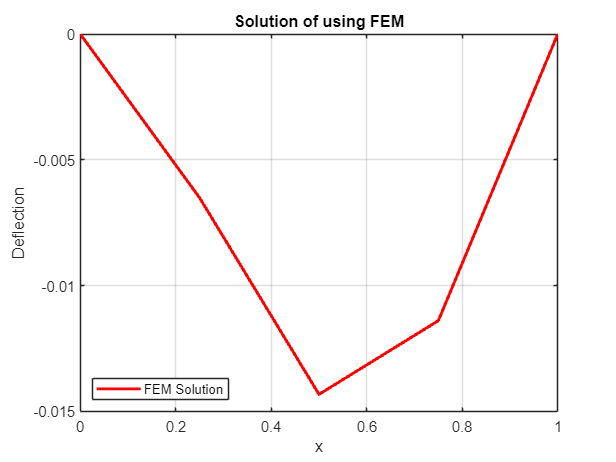


figure;
plot(X, U, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
xlabel("x");
ylabel("Deflection");
title("Solution of using FEM");
legend('Location', 'southwest');
grid on;

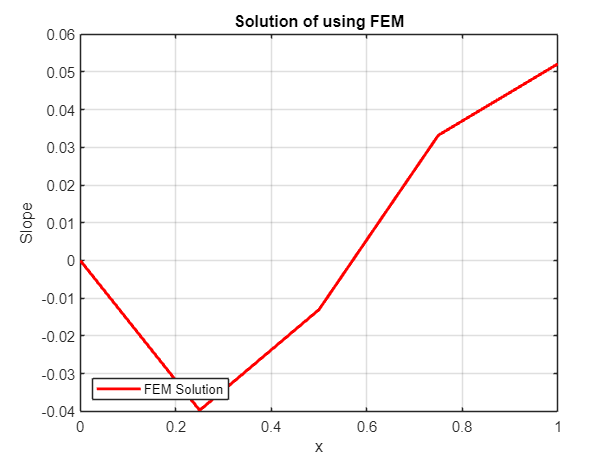


figure;
plot(X, V, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
xlabel("x");
ylabel("Slope");
title("Solution of using FEM");
legend('Location', 'southwest');
grid on;

function phi_e = H_Cubic_beam_shapefunction_x(x0)
    %Hermite cubic shape functions
    % Define symbolic variables
    syms x x1 h real;

    % in this formula x1 is starting point of the element

    % Define the Hermite cubic shape functions as provided
    N1 = 1 - (3*((x - x1)/h)^2) + (2*((x - x1)/h)^3);


    % for JN reddy N2 here assume inverted slope, So negative must be added for N2 and N4,
    % I'm following Dixit notation, ( Notes Only N2 and N4 are Different )

    N2 = (x - x1) * ((1-((x - x1)/h))^2);
    N3 = (3*((x - x1)/h)^2) - (2*((x - x1)/h)^3);
    N4 = (x - x1)*(((-((x - x1)/h)) + (((x - x1)/h)^2)));
    
    phi_e = sym(zeros(4,1));
    
    phi_e(1) = N1;
    phi_e(2) = N2;
    phi_e(3) = N3;
    phi_e(4) = N4;
    phi_e = subs(phi_e,x1,x0);

end
function B = matrixToColumnVector(A)
    % matrixToColumnVector converts a n x 2 matrix into a 2n x 1 column vector.

    % Check if the input matrix A has exactly 2 columns
    if size(A, 2) ~= 2
        error('Input matrix must have exactly 2 columns');
    end

    % Reshape the matrix A to a column vector
    B = reshape(A', [], 1);

    % Optionally, display the output vector
    % disp(B);  % Uncomment this line if you want to display the vector
end
function A = columnVectorToMatrix(B)
    % columnVectorToMatrix converts a 2n x 1 column vector into a n x 2 matrix.

    % Check if the length of vector B is even
    if mod(length(B), 2) ~= 0
        error('Length of input vector must be even');
    end

    % Calculate the number of rows for the matrix A
    numRows = length(B) / 2;

    % Reshape the vector B to a matrix A of size n x 2
    A = reshape(B, 2, numRows)';

    % Optionally, display the output matrix
    % disp(A);  % Uncomment this line if you want to display the matrix
end


